# IWFM and SAFE Calculation for One node 

## Problem description

The example is shown in the following figure. To minimize the influence of the boundary conditions in the river, I used only 2 nodes as constant head boundary conditions highlighted with green circles.

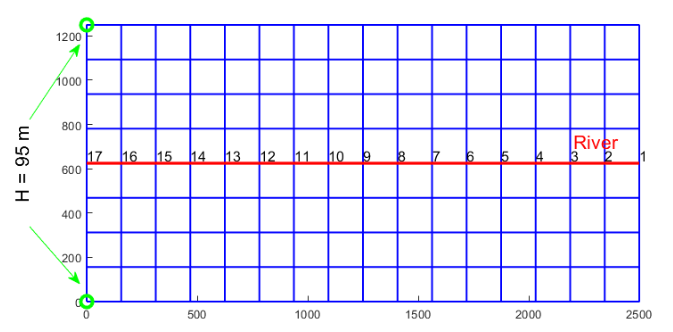

Cross section of the example along the river:

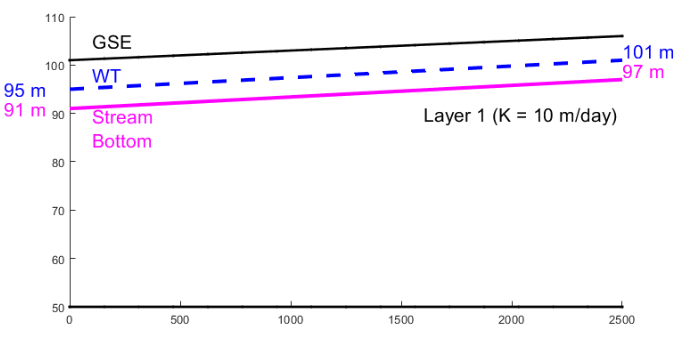

The water table (WT) line corresponds to the initial conditions.

## Calculations

In the following we calculate the stream water groundwater exchange for on node at the last time step of the simulation.

Each time step, the IWFM executes several Newton Raphson iterations. The data correspond to the last iteration of the Newton Raphson of the last time step.

In this document I picked the node with id 10.

### Common parameters

Below we set a few common parameters. 

The length $L$ of the river segment of the node is equal to:

L = 156.25;

The area of influence in this example can be calculated as: 

A = L*156.25;

Nevertheless, in IWFM the calculation is executed using the standard finite element formula.

The horizontal and vertical hydraulic conductivity $K_h$ and $K_v$ are: 

Kh = 10;
Kv = 10;

The conductivity $K_{\textrm{cl}}$ and thickness $e_{\textrm{cl}}$ of the clogging layer are: 

K_cl = 2;
e_cl = 1;

The thickness of the aquifer $W_{\textrm{aq}}$ and stream bottom $h_b$ for the selected node are: 

W_aq = 53.1875;
hb = 93.6250;

The thickness of the aquifer is measured from the ground surface elevation which is $\textrm{GSE}\;$

GSE = 103.1875;

The absolute elevation of the bottom of the aquifer is ${\textrm{El}}_{\textrm{bot}}$

El_bot = GSE - W_aq

El_bot = 50

The wetted perimeter is expressed as $W=f\left(\max \left(h,h_s \right)\right)$,  where $f$is a user defined function as rating table. A plot of the function is shown in the following figure.

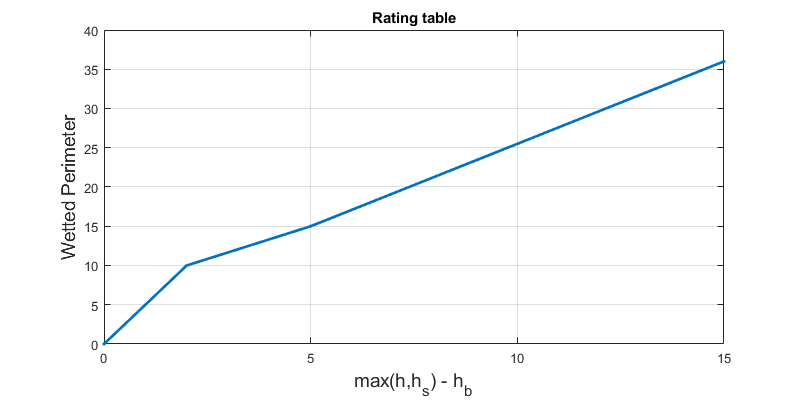

ratingTable = [0 0 0;...
    2 734.94 10;...
    5 3299.29 15;...
    15 19033.6 36;...
    25 41568.45 2000];
clf
set(gcf,'position',[0,0,800,400]);
plot(ratingTable(1:4,1), ratingTable(1:4,3),'.-', "LineWidth",2)
hold on
xlabel('max(h,h_s) - h_b',"FontSize",14)
ylabel('Wetted Perimeter',"FontSize",14)
title('Rating table')
grid on
hold off

The groundwater head $h$ and stream head $h_s$ for the node 10 are:

h = 97.0287;
hs = 97.0269;

For IWFM (I'm referring to code not to the manual) stream head is expressed as elevation from the common datum.

To avoid confusion, I'll denote stream stage as $h_{\mathrm{stage}}$ 

By interpolating the rating table, we find that the wetter perimeter $W_{\mathrm{per}}$ for the node 10 where $\mathrm{max}\left(h,h_s \right)-h_b =3\ldotp 4037$ is:

Wper = 12.3395;

Last we calculate the head difference which is common for all methods. 


$$H_{\mathrm{diff}} =\mathrm{max}\left(h_s ,h_b \right)-\mathrm{max}\left(h,h_b \right)$$


Hdiff = max(hs, hb) - max(h, hb)

Hdiff = -0.0018

### IWFM

In IWFM code (not in the documentation) the unit conductance is first calculated in a preprocessing step before the simulation starts and it is equal to 


$$K_u =t_{\mathrm{sc}} \frac{K_{\mathrm{cl}} }{e_{\mathrm{cl}} }L$$


where $t_{\textrm{sc}}$is scaling parameter to account for the time units. In our example the time step is a month and therefore in IWFM $t_{\textrm{sc}} =30$

For the node 10 this is equal to:

Kunit = 30*K_cl*L/e_cl

Kunit = 9375

Next the conductance $C_s =K_{u\;} W_{\textrm{per}}$ is: 

Cs = Kunit *  Wper;
fprintf('Cs = %f\n',Cs)

Cs = 115682.812500


And finally, the stream-groundwater interaction $Q_{\textrm{sint}}$ is

Qsint = Cs .* Hdiff;
fprintf('Qsint = %f\n',Qsint)

Qsint = -208.229063


### SAFE

#### Pre - processing

The following parameters of the SAFE method do not change during the simulation and can be calculated prior to the simulation.

SAFE width 


$$W^{\mathrm{safe}} =\frac{A}{2L}$$


Wsafe = A / (2 * L)

Wsafe = 78.1250

 The SAFE grid size $G^{\textrm{safe}} =2W^{\textrm{safe}}$ which has nothing to do with any mesh element is computed as

Gsafe = 2 * Wsafe

Gsafe = 156.2500

### Simulation step

#### Flat conductance

Calculate the river stage $h_{\textrm{stage}}$

h_stage = hs - hb

h_stage = 3.4019

Calculate the saturated thickness $D_{\textrm{aq}}$

Daq = h - El_bot % Groundwater head - Bottom of the aquifer

Daq = 47.0287

Next, the degree of penetration is computed as

 
$$d_p^N =\;\;\frac{h_{\textrm{stage}} }{D_{\textrm{aq}} }$$
 

d_Np = h_stage / Daq

d_Np = 0.0723

The average saturated thickness $D_{\textrm{aq}}$ is also used to calculate the normalized wetted perimeter: 


$$W_p^N =\frac{W}{D_{\textrm{aq}} }$$


W_Np = Wper / Daq

W_Np = 0.2624

Next, we compute the $\kappa$ value:


$$\kappa =e^{-\pi W_p^N }$$


kappa = exp(-pi*W_Np)

kappa = 0.4385

The conductance for a flat recharge area is calculated as


$$\Gamma_{\textrm{flat}} =\frac{1}{2\left\lbrace 1+\frac{1}{\pi }\ln \left(\frac{2}{1-\sqrt{\kappa }}\right)\right\rbrace }$$


G_flat = 1 / (2 * (1 + (1/pi) * log(2/(1-sqrt(kappa)))))

G_flat = 0.3193

#### Isotropic case

If the aquifer is isotropic the conductance is calculated as


$$\Gamma_{\mathrm{iso}} =\Gamma_{\mathrm{flat}} \left\lbrack 1+\alpha_1 {\;d}_p^N +\alpha_2 \;{\left(d_p^N \right)}^2 \right\rbrack$$


where the coefficients $a_1 ,a_2$ are estimated as a function of the normalized degree of penetration $d_p^N$ and normalized wetter perimeter $W_p^N$

According to the table

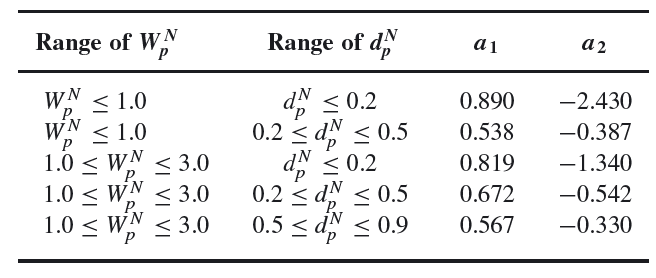

The values $a_1$ and $a_2$ get the values:

a1 = 0.890;
a2 = -2.430;

Therefore $\Gamma_{\mathrm{iso}}$ is calculated as: 

G_iso = G_flat * (1 + a1 * d_Np + a2 * (d_Np^2))

G_iso = 0.3358

#### Excess far distance

To estimate the excess far distance $\Delta_{\textrm{iso}}^{\textrm{safe}}$ we must calculate the half river width $B^{\textrm{safe}} =0\ldotp 5\;W_r$ where $W_r$ is the river width.

The river width is not known but it can be estimated from the equivalent rectangle for the IWFM cross-section. If we preserve the river stage $H^{\mathrm{rect}} =h_{\mathrm{stage}}$ and the wetted perimeter $W^{\mathrm{rect}} =W_{\mathrm{per}}$, then the wetted perimeter can be expressed as $W_{\mathrm{per}} =2h_{\mathrm{stage}} +W_r$. The wetted perimeter is interpolated from user defined rating tables (see the common parameters) and the river width can be computed as $W_r =W_{\mathrm{per}} -2h_{\mathrm{stage}}$

Wr = Wper - 2.*h_stage

Wr = 5.5357

Bsafe = 0.5.*Wr

Bsafe = 2.7679

 Then the far distance is calculated as


$$\Delta_{\textrm{iso}}^{\textrm{safe}} =\frac{G^{\textrm{safe}} }{4}-B^{\textrm{safe}} -2D_{\textrm{aq}}$$


Delta_iso = Gsafe/4 - Bsafe - 2*Daq

Delta_iso = -57.7628

Finally, the extended value of the dimensionless conductance is calculated as: 


$$\Gamma_{\mathrm{iso}-\Delta } =\frac{\Gamma_{\mathrm{iso}} }{1+\Gamma_{\mathrm{iso}} \frac{\Delta_{\mathrm{iso}}^{\mathrm{safe}} }{D_{\mathrm{aq}} }}$$


G_iso_D = G_iso / (1 + G_iso * (Delta_iso/Daq))

G_iso_D = 0.5714

#### Correction for clogging

In IWFM a clogging layer is always assumed to exist, therefore the final conductance is calculated as


$$\Gamma_{\mathrm{iso}-\Delta -\mathrm{cl}} =\frac{\Gamma_{\mathrm{iso}-\Delta } }{1+\Gamma_{\mathrm{iso}-\Delta } \frac{K_h }{K_{\mathrm{cl}} }\frac{e_{\mathrm{cl}} }{B^{\mathrm{safe}} +h_{\mathrm{stage}} }}$$


G_iso_D_cl = G_iso_D/(1 + G_iso_D * (Kh/K_cl) * (e_cl/(Bsafe+h_stage)))

G_iso_D_cl = 0.3905

To be consistent with the summary, let's call the conductance as $\Gamma_Q$

G_Q = G_iso_D_cl

G_Q = 0.3905

The sw-gw interaction finally can be calculated as


$$Q_{\mathrm{sint}}^{\mathrm{safe}} =2\;{\mathrm{LK}}_h \Gamma_Q \left({\;h}_s -h\right)$$


where $h$ is the groundwater head and $h_s$ is the river head and $K_h$ is the horizontal hydraulic conductivity.

Q_sint_safe = 2.*L.*Kh.*G_Q.*(hs - h)

Q_sint_safe = -2.1968

The above value has the same time units as the hydraulic conductivity which is expressed in days.

Therefore, the actual comparable to IWFM value is

Q_sint_safe*30

ans = -65.9044

## Modflow 

For Modflow the SW-GW interaction is calculated as 


$$Q_{\mathrm{sint}}^{\mathrm{modflow}} =L\cdot W_{\mathrm{per}} \;\frac{K_{\mathrm{cl}} }{e_{\mathrm{cl}} }\left(h_s -h\right)$$


Q_sint_modflow = L*Wper*(K_cl/e_cl)*(hs-h)

Q_sint_modflow = -6.9410

If we include the time conversion parameter $t_{\mathrm{sc}} =30$

Q_sint_modflow * 30

ans = -208.2291

which is very similar to IWFM

## Incipient desaturation

The incipient desaturation is expressed as


$$h_{\mathrm{incip}} =h^o -\frac{B+h_{\mathrm{stage}}^o }{K_h \Gamma_Q }\;\frac{h_{\mathrm{stage}}^o +h_{\mathrm{ce}} +e_{\mathrm{cl}} }{e_{\mathrm{cl}} }$$


The terms with superscript $o$ are supposed to be the values at the previous step. However in IWFM each time step is solved iteratively until there is a converge. Therefore we can use as old values the ones from the previous convergance iteration. For the first iteration we will use the values from the previous step as a starting point.

In the following final head $h$ and river stage $h_s$ are used in place of $h^o$ and $h_s^o$. (I also assume that $B$ is identical to $B^{\textrm{safe}}$)

For the above formula we need the entry pressure term $h_{\mathrm{ce}}$. I assume that this is a user input but it is unknown at the moment, so I'll test a range of values

h_ce = -10:0.1:1;

Calculate the incipient and plot the values for the above range

When the term is positive then $h>h_{\textrm{incip}}$ the connection is saturated.

If the term is negative then the $h_{\textrm{incip}} >h$ and the connection is unsaturated.

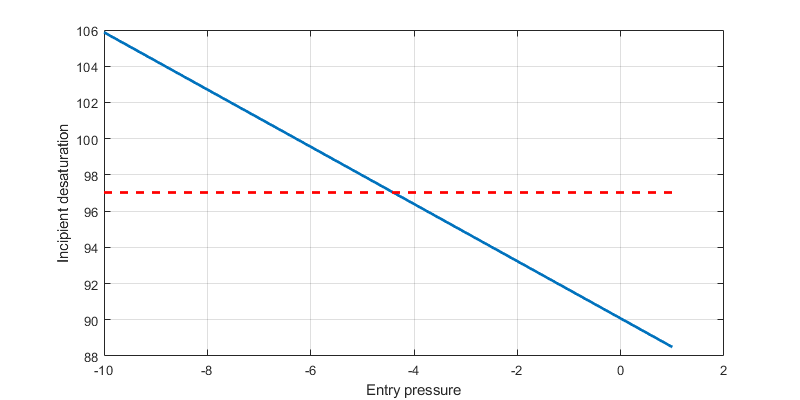

h_incip = h - ((Bsafe + h_stage)./(Kh.*G_Q)) .* ((h_stage + h_ce + e_cl)./(e_cl));
clf
plot(h_ce, h_incip, 'LineWidth',2)
hold on
plot(h_ce, h*ones(1,length(h_ce)), '--r','LineWidth',2)
ylabel('Incipient desaturation')
xlabel('Entry pressure')
grid on

For entry pressure below -4.4 the connection remains saturated.